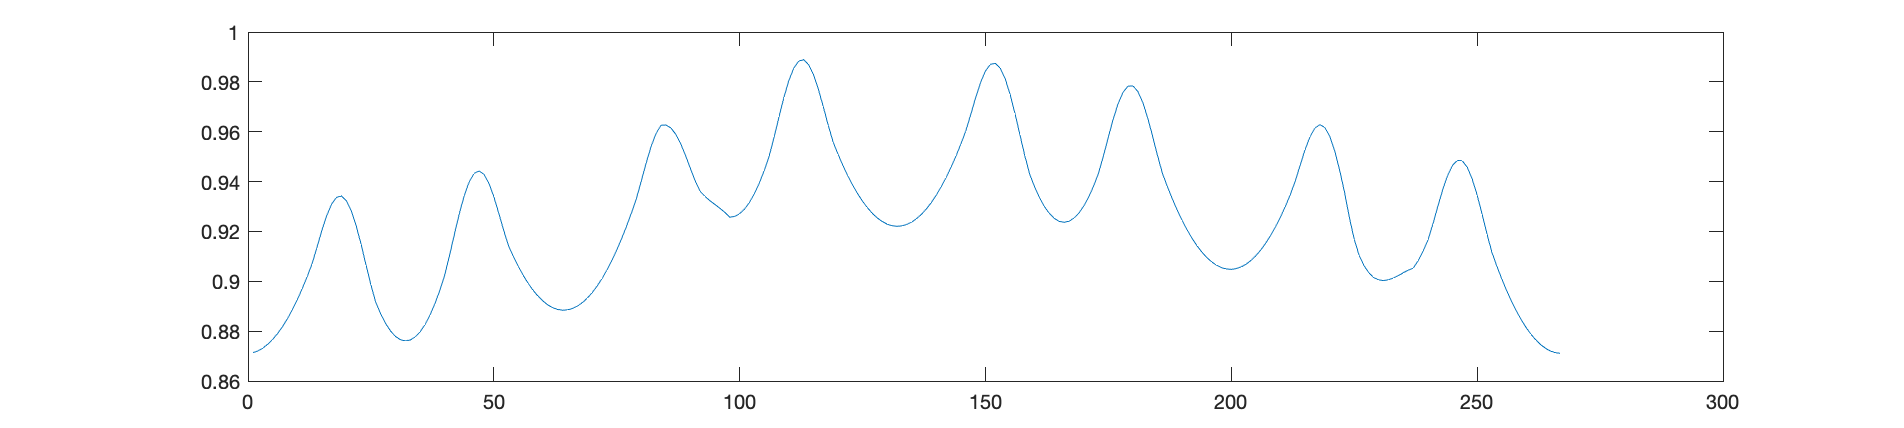

file1 = imread('../images/Meta/14.png');

file = imreducehaze(file1);

[red, blue, yellow, black, white] = splitColor(file);

raux = bwareafilt(red,1);

shapeSignature(raux)

function displaySign(img)
    [red, blue, yellow, black, white] = splitColor(img);
    montage({red, blue, yellow, black, white}, "Size", [1,5]);
end

function numPeaks = shapeSignature(shape)
    rp = regionprops(shape,'Centroid');
    cent = rp.Centroid;
    
    b = cell2mat(bwboundaries(shape,'noholes'));
    
    sign = sqrt((b(:,1)-cent(1)).^2+(b(:,2)-cent(2)).^2);
    [~,idx] = min(sign);
    sign = circshift(sign,-idx)/max(sign);
    sign = smoothdata(sign, 'sgolay');
    numPeaks = sum(islocalmax(sign, 'MinProminence',0.03));
    
    plot(sign);
end

function [red, blue, yellow, black, white] = splitColor(img, maxDist)
    if (nargin < 2)
        maxDist = 0.5;
    end
    
    [H,S,V] = imsplit(rgb2hsv(img));
    
    avgS = mean2(S);
    Saux = S < avgS;
    avgV = mean2(V(Saux));
    
    black = V < avgV;
    white = V >= avgV & S < avgS;
    
    r = num2cell([0.0139, 0.786, 0.786]);
    b = num2cell([0.5889, 0.78, 0.61]);
    y = num2cell([0.1583, 0.68, 1]);
    k = num2cell([0, 0, 0]);
    w = num2cell([0, 0, 1]);
    
    rD = distance(r{:}, H, S, V);
    bD = distance(b{:}, H, S, V);
    yD = distance(y{:}, H, S, V);
    kD = distance(k{:}, H, S, V);
    wD = distance(w{:}, H, S, V);
    
    red = rD < bD & rD < yD & rD < kD & rD < wD & rD < maxDist;
    blue = bD < rD & bD < yD & bD < kD & bD < wD & bD < maxDist;
    yellow = yD < rD & yD < bD & yD < kD & yD < wD & yD < maxDist;
end

function [dist] = distance(H, S, V, H2, S2, V2)
    cos1 = cos(2*pi * H) .* S;
    sin1 = sin(2*pi * H) .* S;
    
    cos2 = cos(2*pi * H2) .* S2;
    sin2 = sin(2*pi * H2) .* S2;

    dist = sqrt((cos2 - cos1).^2 + (sin2 - sin1).^2);
end




function O = PerformAWB(I, p)
%
% Function O = PerformAWB(I, p) implements Auto White Balance (AWB)
% functionality as proposed in-
% H. Garud, A. K. Ray, M. Mahadevappa, J. Chatterjee, and S. Mandal, �A 
% fast auto white balance scheme for digital pathology,� in Biomedical and 
% Health Informatics (BHI), 2014 IEEE EMBS International Conference on , 
% vol., no., pp.153,156, 1-4 June 2014.
% 
%
% The supported image class for input image I is RGB(uint8)
%
%   2015 (c) Amit Suveer, Uppsala University, Sweden
%
%       Ver 1.0     28 May 2015
%
% --------------------------
% Sample Usage 
% --------------------------
% I = imread('Test.jpg');
% O = PerformAWB(I);
% figure, subplot 121, imshow(I), subplot 122, imshow(O);
%
%   2015 (c) Amit Suveer, Uppsala University, Sweden
% All rights reserved.
% 
% Permission is hereby granted, to use, copy, modify, and distribute this code 
% (the source files) and its documentation for research purposes only, 
% provided that the copyright notice in its entirety appear in all copies 
% of this code, and the original source of this code. 
%
% In no circumstantial cases or events the author(s) of this particular 
% be liable to any party for direct, indirectm special, incidental, or consequential 
% damages if any arising out of due usage. Uppsala University and the author(s)
% disclaim any warranty, including but not limited to the implied warranties 
% of merchantability and fitness for a  particular purpose. The disclosure 
% is provided hereunder "as in"  voluntarily for community development and 
% the contributing parties have  no obligation to provide maintenance, 
% support, updates, enhancements, or modification.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%   
%% Default Parameters 
if nargin == 1
    p = 96; 
end
p = 100-p; % always the top % is considered
szI = size(I);
if(length(szI) < 3)
    error ('Input image should be in RGB color space')
end
%% Illumination Estimation
    % Step 1 : White Patch Retinex Mathod (WPR)
    [iR, iG, iB] = EstimateIlluminantRGB(I, p);    
    
    % Corelated Color Temperature (CCT) Estimation
    
    % Compte for estimated Illuminant
    iEstm = [iR, iG, iB];
    CCT_Estm = EstimateCCT(iEstm);
    % Compute for reference / canonical illuminant
    iRef = [iG, iG, iG];
    CCT_Ref = EstimateCCT(iRef);
    %% Parameter Estimation
    
    % Computing Gain Factor and offset parameters    
    K = ComputeGainFactorMatrix(iEstm);    
    T = ComputeOffsetMatrix(K, CCT_Estm, CCT_Ref);
    %% White Balance Correction 
    
    O = PerformWhiteBalanceCorrection(I, K, T);
    
%     subplot(1,2,1), imshow(I);
%     subplot(1,2,2), imshow(O);
    
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [Rc, Gc, Bc] = EstimateIlluminantRGB(I, p)
    R = I(:,:,1);
    G = I(:,:,2);
    B = I(:,:,3);
    % Estimate Illuminant
    Rc = EstimateIlluminantGrey(R, p);
    Gc = EstimateIlluminantGrey(G, p);
    Bc = EstimateIlluminantGrey(B, p);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function Ic = EstimateIlluminantGrey(I, p)
    Ic = 0;
    
    L = 256;
    sz = size(I);
    pxlTh = (p*sz(1)*sz(2))/100;    
    histI = imhist(I);
    Imin = min(min(I));
    Imax = max(max(I));
    % Run the loop from 0 to L-2 or Imin to Imax-1
    for k=Imin:(Imax-1)
    
        % Total number of pixels from k to L-1
        j = double(k+1); % Since MATLAB follows 1 indexing 
        cnt1 = sum(histI(j:L));
        % Total number of pixels from k+1 to L-1
        j = j+1; % from the next grey value 
        cnt2 = sum(histI(j:L));
        if( (cnt1 > pxlTh) && (cnt2 < pxlTh) )
            Ic = k;
             break;
        end
    end    
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function CCT = EstimateCCT(iEstm)
% Constant parameters from 
    A0 = -949.86315;
    A1 = 6253.80338;
    A2 = 28.70599;
    A3 = 0.00004;
    t1 = 0.92159;
    t2 = 0.20039;
    t3 = 0.07125;
    xe = 0.3366;
    ye = 0.1735;
    % Calculate x and y from estimated illuminant values
    XYZ_Conv_matrix = [ 0.4124 0.3576 0.1805; 
                        0.2126 0.7152 0.0722; 
                        0.0193 0.152 0.9505];
    
    XYZ = XYZ_Conv_matrix * double(iEstm');         
    
    x = XYZ(1) / (sum(XYZ));
    y = XYZ(2) / (sum(XYZ));
    H = -((x-xe)/(y-ye));
    CCT = A0 + (A1*exp(H/t1)) + (A2*exp(H/t2)) + (A3*exp(H/t3));
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [K] = ComputeGainFactorMatrix(iEstm)
    % k(r,g,b) = ig / i(r,g,b)
    iEstm = double(iEstm);
    iEstm_R = iEstm(1);
    iEstm_G = iEstm(2);
    iEstm_B = iEstm(3);
    iRef_R = iEstm_G; 
    iRef_G = iEstm_G; 
    iRef_B = iEstm_G;
    Kr = iRef_R / iEstm_R; 
    Kg = iRef_G / iEstm_G;
    Kb = iRef_B / iEstm_B;
    K = [Kr, 0, 0;
          0, Kg, 0;
          0, 0, Kb];
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function T = ComputeOffsetMatrix(K, CCT_Estm, CCT_Ref)
    A = 100;
    Kr = K(1,1);
    Kb = K(3,3);
    Tr = max(1, (CCT_Estm - CCT_Ref)/A ) * (Kr-1);
    Tg = 0;
    Tb = max(1, (CCT_Ref - CCT_Estm)/A ) * (Kb-1);
    T = [Tr; Tg; Tb];
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function O = PerformWhiteBalanceCorrection(I, K, T)
    sz = size(I);
    O = uint8(zeros(sz));
  
    for x = 1:sz(1)
        for y = 1:sz(2)
            Fxy = double([I(x,y,1), I(x,y,2), I(x,y,3)]');
            FWB = K * Fxy + T;
            
            for p=1:3
                O(x,y,p) = uint8(FWB(p));
            end
        end    
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%